#### Modelo SEIR Discreto


$$\[
S(k+1) = S(k) + TS \left( B + \nu R(k) - \frac{[\beta+U(k)]\cdot I(k)\cdot S(k)}{S(k)+E(k)+I(k)+R(k)} - dS(k) \right)
\]

\[
E(k+1) = E(k) + TS \left( \frac{[\beta+U(k)]\cdot I(k) \cdot S(k)}{S(k)+E(k)+I(k)+R(k)} - \alpha E(k) - d E(k) \right)
\]

\[
I(k+1) = I(k) + TS \left( \alpha E(k) - \gamma I(k) - d I(k) \right)
\]

\[
R(k+1) = R(k) + TS \left( \gamma I(k) - \nu R(k) - d R(k) \right)
\]$$


x_act=[0.1431
    0.0092
    0.0092
    0.8384 ];
U=ones(1,101)*0.5;
Ts=10;
k=1;

B = 0.334347777716906; %B
d = 0.342692168641646; %d
alpha = 0.0904963402600036; %alpha_
gamma = 0.104149917959794; %gamma_
beta = 0.189760832657602; %beta_dos;
nu = 0.00862168642730242; %nu_


C=[0 0 0 1];


% x_pre=...
%     [x_act(1,k)+Ts*((B/1000)+(nu/10)*x_act(4,k)-((((beta+U(k))*x_act(3,k)*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k)))-(d/1000)*x_act(1,k))
%     x_act(2,k)+Ts*(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))-alpha*x_act(2,k)-(d/1000)*x_act(2,k))
%     x_act(3,k)+Ts*(alpha*x_act(2,k)-gamma*x_act(3,k)-(d/1000)*x_act(3,k))
%     x_act(4,k)+Ts*(gamma*x_act(3,k)-(nu/10)*x_act(4,k)-(d/1000)*x_act(4,k))];



Phi_S=...
    [1+(-(((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-(d/1000))*Ts
    (((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
    0
    0];

Phi_E=...
    [(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
    1 + (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-alpha-(d/1000))*Ts
    Ts*alpha
    0];

Phi_I=...
    [(-(((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    ((((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    1+(-gamma-(d/1000))*Ts
    gamma*Ts];

Phi_R=...
    [((nu/10)+(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    0
    1+(-(nu/10)-(d/1000))*Ts];

Phi=[Phi_S Phi_E Phi_I Phi_R];


Mo=[C;C*Phi;C*Phi^2;C*Phi^3;C*Phi^4];

Numero_De_Condicion_Mo=cond(Mo)

Numero_De_Condicion_Mo = 94.2360

## Generacion de datos

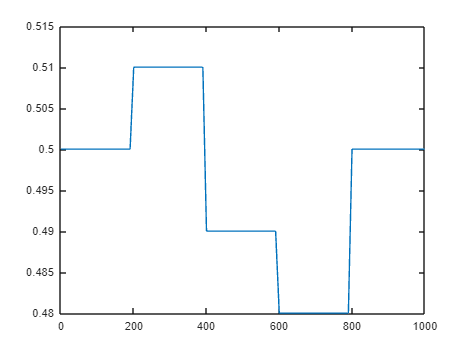

mdl = 'SEIRS_2';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
set_param(path, 'Ruido',1);
set_param(path,'Var_ruido',num2str(1e-8));
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;
Dias = 1000; % Tiempo máximo de la simulación
Ts = 10; % Período de muestreo definido anteriormente
t = (0:Ts:Dias)'; % Instantes de simulación
N = length(t);
U = timetable(seconds(t),[0.5*ones(1,(N-1)/5) 0.51*ones(1,(N-1)/5) 0.49*ones(1,(N-1)/5) 0.48*ones(1,(N-1)/5) 0.5*ones(1,(N-1)/5+1)]');
figure
plot(t,U.Var1)

dir_modelo = "SEIRS_2.slx";
sim_datos_exp=sim(dir_modelo);
x_teo=[sim_datos_exp.S.signals.values'
    sim_datos_exp.E.signals.values'
    sim_datos_exp.I.signals.values'
    sim_datos_exp.R.signals.values'];
y=sim_datos_exp.R.signals.values;

## Inicializacion Filtro

x0 = [S0 E0 I0 R0]';
n = length(x0);
P0 = 1e-6*eye(n);
Q = zeros(4);
Q(1,1)=1e-4;
Q(2,2)=1e-6;
Q(3,3)=1e-6;
Q(4,4)=1e-4;
R_k = 1e-9;

x_act = zeros(n,N);
P_act_traza = zeros(N,1);
K_norma = zeros(N,1);
de_x = zeros(n,N);
N_cond = zeros(N,1);
x_pre = x0;
P_pre = P0;
U=U.Var1;

## Filtro

for k=1:N
    % Corrección del estado
    K = P_pre*C'/(C*P_pre*C' + R_k);
    x_act(:,k) = x_pre + K*(y(k) - C*x_pre);
    P_act = (eye(n)-K*C)*P_pre;
    P_act = (P_act + P_act')/2;
    % Actualización del estado para el siguiente paso (i+1)
    x_pre=...
        [x_act(1,k)+Ts*((B/1000)+(nu/10)*x_act(4,k)-((((beta+U(k))*x_act(3,k)*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k)))-(d/1000)*x_act(1,k))
        x_act(2,k)+Ts*(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))-alpha*x_act(2,k)-(d/1000)*x_act(2,k))
        x_act(3,k)+Ts*(alpha*x_act(2,k)-gamma*x_act(3,k)-(d/1000)*x_act(3,k))
        x_act(4,k)+Ts*(gamma*x_act(3,k)-(nu/10)*x_act(4,k)-(d/1000)*x_act(4,k))];


    Phi_S=...
        [1+(-(((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-(d/1000))*Ts
        (((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
        0
        0];

    Phi_E=...
        [(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
        1 + (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-alpha-(d/1000))*Ts
        Ts*alpha
        0];

    Phi_I=...
        [(-(((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        ((((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        1+(-gamma-(d/1000))*Ts
        gamma*Ts];

    Phi_R=...
        [((nu/10)+(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        0
        1+(-(nu/10)-(d/1000))*Ts];

    Phi=[Phi_S Phi_E Phi_I Phi_R];
    P_pre = Phi*P_act*Phi' + Q;
    % Vectores con información
    N_cond(k) = cond(obsv(Phi,C));
    P_act_traza(k) = trace(P_act);
    K_norma(k) = norm(K);
    de_x(:,k) = sqrt(diag(P_act));
end

## Grafica de resultados 1

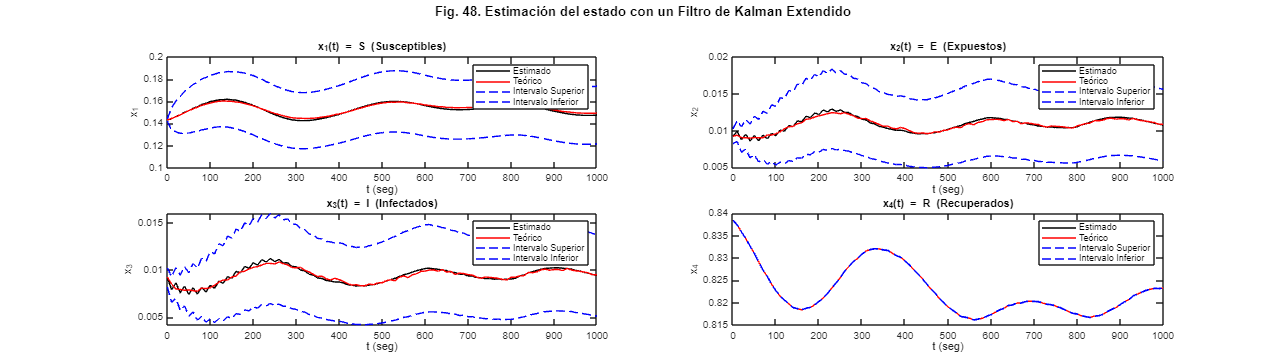

figure('Units','normalized','Position',[0 0 1 0.5])
sgtitle({'Fig. 48. Estimación del estado con un Filtro de Kalman Extendido';''},'FontSize',12,'FontWeight','bold')
x_names = {'S (Susceptibles)', 'E (Expuestos)', 'I (Infectados)', 'R (Recuperados)'};

for k = 1:4
    subplot(2,2,k) % Ajuste para cuatro variables en un arreglo de 2x2
    plot(t, x_act(k,:)','k', ...                     % Estado estimado
         t, x_teo(k,:),'r', ...                     % Estado teórico
         t, (x_act(k,:) + de_x(k,:))','b--', ...    % Intervalo superior
         t, (x_act(k,:) - de_x(k,:))','b--')        % Intervalo inferior
    xlabel('t (seg)')
    ylabel(['x_' num2str(k)])
    title(['x_' num2str(k) '(t) = ' x_names{k}])
    legend({'Estimado', 'Teórico', 'Intervalo Superior', 'Intervalo Inferior'})
end

## Grafica de resultados 2

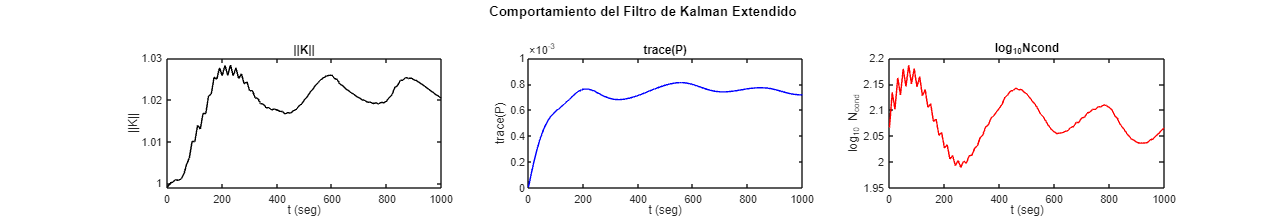

figure('Units','normalized','Position',[0 0 1 0.3])
sgtitle({'Comportamiento del Filtro de Kalman Extendido';''},'FontSize',12,'FontWeight','bold')

subplot(1,3,1)
plot(t, K_norma, 'k')
xlabel('t (seg)'), ylabel('||K||')
title('||K||')

subplot(1,3,2)
plot(t, P_act_traza, 'b')
xlabel('t (seg)'), ylabel('trace(P)')
title('trace(P)')

subplot(1,3,3)
plot(t, log10(N_cond), 'r')
xlabel('t (seg)'), ylabel('log_{10} N_{cond}')
title('log_{10}Ncond')


syms S E I R u nu alpha gamma beta B d Ts
juas2=[0;0;0;0];
dS_dt = B/1000+(nu/10*R)-(((beta+u)*I)/(S+E+I+R))*S-d/1000*S;
dE_dt = (((beta+u)*I)/(S+E+I+R))*S-alpha*E-d/1000*E;
dI_dt = alpha*E-gamma*I-d/1000*I;
dR_dt = gamma*I-nu/10*R-d/1000*R;
Model_eqs = [dS_dt; dE_dt; dI_dt; dR_dt];
Discrete_model=Model_eqs*Ts+[S;E;I;R];
A=jacobian(Model_eqs, [S E I R]);
Phi_2=eye(4)+A*Ts;

params=zeros(6,1);
params(1) = 0.334347777716906; %B
params(2) = 0.342692168641646; %d
params(3) = 0.0904963402600036; %alpha_
params(4) = 0.104149917959794; %gamma_
params(5) = 0.189760832657602; %beta_dos;
params(6) = 0.00862168642730242; %nu_

for k=1
    x_pre=double(subs(Discrete_model,[B d alpha gamma beta nu S E I R u Ts],[params(1) params(2) params(3) params(4) params(5) params(6) x_act(1,k) x_act(2,k) x_act(3,k) x_act(4,k) U(k) 10]));
    Phi_num =double(subs(Phi_2,[B d alpha gamma beta nu S E I R u Ts],[params(1) params(2) params(3) params(4) params(5) params(6) x_act(1,k) x_act(2,k) x_act(3,k) x_act(4,k) U(k) 10]));
    
end


